# Approximate Square Wave

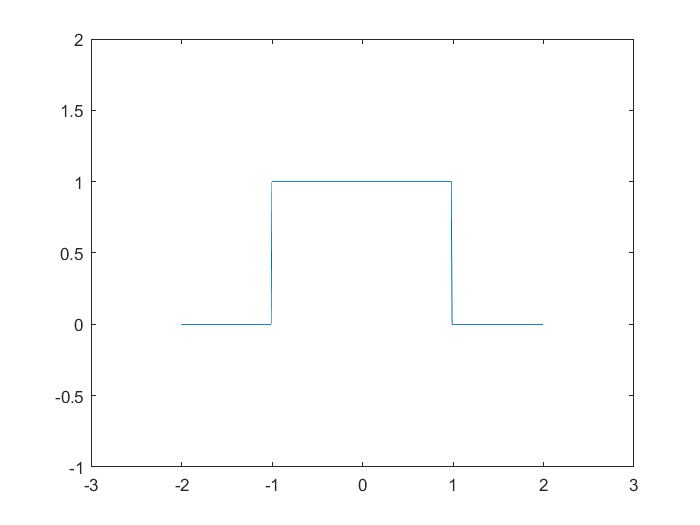

clear; clc;
dx = 0.01;
L = 4;
x = -L/2:dx:L/2;

fx = ones(size(x));
fx(1:floor(length(x)/4)) = 0;
fx(floor(3*length(x)/4):length(x)) = 0;
plot(x,fx);
axis([-3 3 -1 2]); 

## Approximation

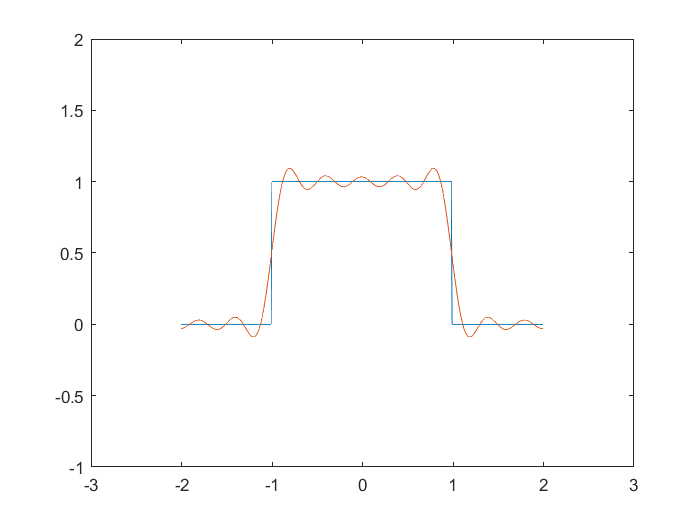

A0 = (2/L) * sum(fx.*cos(2*pi*0*x/L)) * dx;
ffs = A0/2;
for n=1:10
    hold off;
    plot(x,fx);
    axis([-3 3 -1 2]);   

    An = (2/L) * sum(fx.*cos(2*pi*n*x/L)) * dx;
    Bn = (2/L) * sum(fx.*sin(2*pi*n*x/L)) * dx;
    ffs = ffs + An*cos(2*pi*n*x/L) + Bn*sin(2*pi*n*x/L);
    
    hold on;
    plot(x,ffs);
    drawnow;
    pause(0.05);
end